# Parametric Amplifiers

The model features two oscillators, each of which resembels the model of a parametric amplifier as presented by 

Li, D. & Shaw, S. W. The effects of nonlinear damping on degenerate parametric amplification.NonlinearDynamics 2020 102:4102,2433–2452 (4 Dec. 2020) [https://doi.org/10.1006/jsvi.1995.0547](https://doi.org/10.1006/jsvi.1995.0547) 

The model is extended to a two- dimensional setting 

                              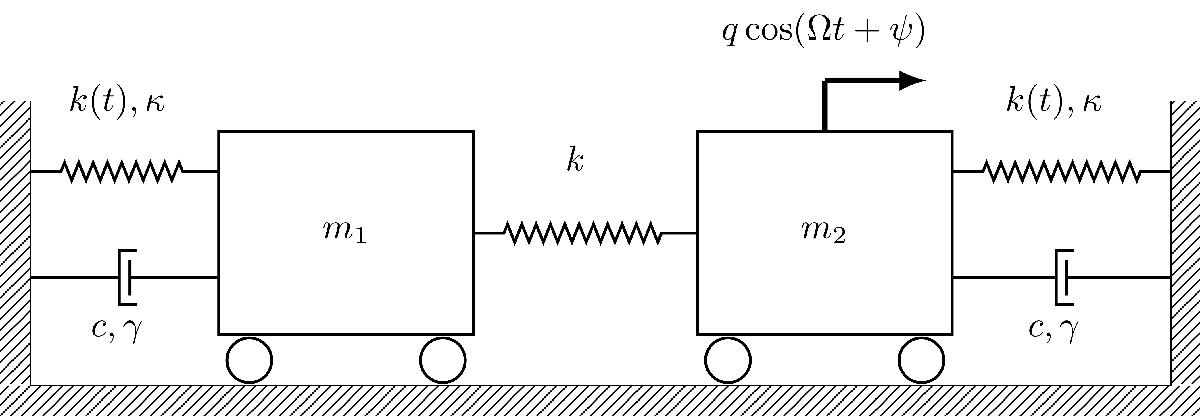

The parametric excitation of the linear stiffness is of the form $k(t) = k(1 + \mu \cos (\Omega t))$.

## system parameters

clear all
mus = [0.05, 0.05+1/3*0.1, 0.05+2/3*0.1 0.15]

mus =     0.0500    0.0833    0.1167    0.1500


psi = pi/4;

## Generate model

ii = 1;

for mu = mus
[ M,C,K,fnl,fext] = build_model(psi,mu);

## Dynamical system setup

We consider the forced  and parametrically excited system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{g}(\mathbf{x},\dot{\mathbf{x}},\Omega t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{G}(\mathbf{z},\phi),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{G}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{g}(\mathbf{x, \dot{x}},\phi)\\
\mathbf{0}
\end{array}\right]$.

% Dynamical System
DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M, 'C', C, 'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')



## Add forcing

The dynamical system is forced externally and parametrically with $\mathbf{g(x},\Omega t) = 
\mu\left[\begin{array}{cc} k & 0 \\ 0 &  k \end{array}\right] \cos(2\Omega t) \mathbf{x} 
+
\left[\begin{array}{cc}   0 \\ q \cos (\Omega t + \psi)   \end{array}\right]$

Parameters are chosen as $\epsilon = 1, q = 0.2$

% External forcing
DS.add_forcing(fext,1);

## Linear Modal Analysis 

% Analyse spectrum
[V,D,W] = DS.linear_spectral_analysis();


**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.5,'notation','multiindex')

%Choose Master subspace
masterModes = [1,2];
S.choose_E(masterModes);

## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 5; % Approximation order

setup options

outdof = [1,2];
set(S.Options, 'reltol', 0.5,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^7, 'nRho', 200, 'nPar', 200, 'nPsi', 200, 'rhoScale', 6 )
set(S.FRCOptions, 'method','level set') % 'continuation ep'
set(S.FRCOptions, 'outdof',outdof)


choose frequency range around the master mode frequency

omega0 = imag(S.E.spectrum(1));
OmegaRange =omega0*[0.9 1.2];

%Omega dependence of non-autonomous coefficients
set(S.FRCOptions,'omDepNonAuto',true)


Extract forced response curve

startFRCSSM = tic;
FRCs(ii).FRC  = S.extract_FRC('freq',OmegaRange,order);
timings(ii).FRCSSM = toc(startFRCSSM);
figFRC = gcf;

## Verification: Collocation using [coco](https://sourceforge.net/p/cocotools/wiki/Home/)

Dankowicz, H., & Schilder, F. (2013).  *Recipes for Continuation,* SIAM Philadelphia. [<https://doi.org/10.1137/1.9781611972573](https://doi.org/10.1137/1.9781611972573)>


 The first 4 eigenvalues are given as 
  -0.0100 + 0.9999i
  -0.0100 - 0.9999i
  -0.0100 + 1.7320i
  -0.0100 - 1.7320i



sigma_out = 1
sigma_in = 1


parSubRange =     0.9000    1.1999


*****************************************
Calculating FRC using SSM with master subspace: [1  2]
sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.90E-03 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 9.23E-03 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.14E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.41E-02 MB
gamma = 
  -0.0150 + 0.0749i
  -0.0008 - 0.0081i



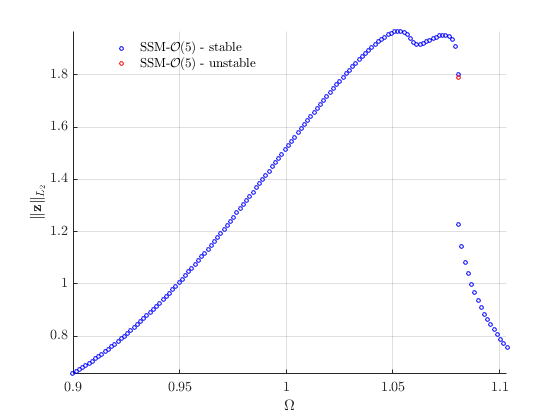

Total time spent on FRC computation upto O(5) = 00:01:09



 Run='FRC1': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.24e-01  1.22e+01    0.0    0.0    0.0
   1   1  3.56e-01  2.92e+00  1.44e-01  1.17e+01    0.0    0.1    0.0
   2   1  4.95e-01  1.96e+00  7.27e-02  1.12e+01    0.1    0.3    0.0
   3   1  8.82e-01  1.03e+00  8.55e-03  1.08e+01    0.1    0.4    0.0
   4   1  1.00e+00  1.36e-01  6.74e-06  1.07e+01    0.3    0.5    0.0
   5   1  1.00e+00  3.16e-04  5.07e-11  1.07e+01    0.3    0.8    0.1
   6   1  1.00e+00  2.58e-09  2.66e-15  1.07e+01    0.3    0.8    0.1

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1         amp2
    0  00:00:02   1.0739e+01      1  EP      8.9995e-01   6.9817e+00   1.0000e+00   4.3857e-01   5.2810e-01
    1  00:00:03   1.0646e+01      2  EP      8.9995e-01   6.9817e+00   1.0000e+00   4.3855e-01

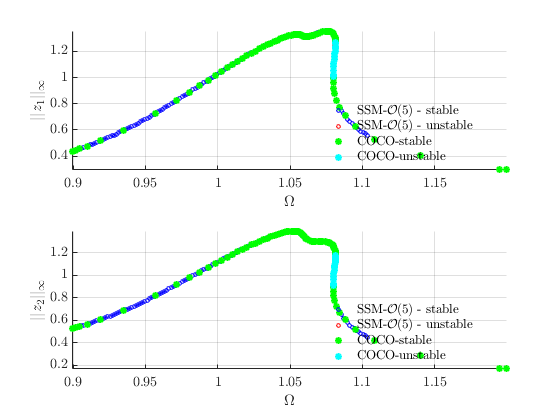


 The first 4 eigenvalues are given as 
  -0.0100 + 0.9999i
  -0.0100 - 0.9999i
  -0.0100 + 1.7320i
  -0.0100 - 1.7320i



sigma_out = 1
sigma_in = 1


parSubRange =     0.9000    1.1999


*****************************************
Calculating FRC using SSM with master subspace: [1  2]
sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.90E-03 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 9.23E-03 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.14E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.41E-02 MB
gamma = 
  -0.0150 + 0.0749i
  -0.0008 - 0.0081i



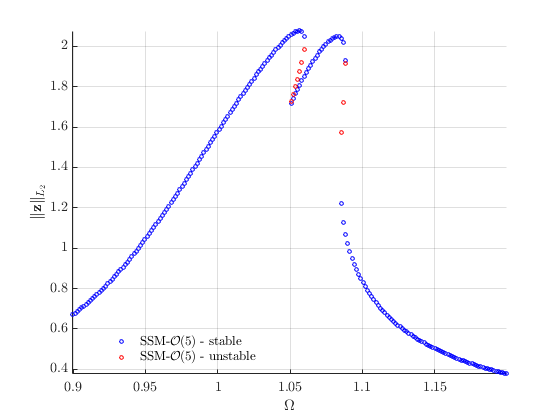

Total time spent on FRC computation upto O(5) = 00:01:10



 Run='FRC1': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.32e-01  1.22e+01    0.0    0.0    0.0
   1   1  3.52e-01  2.92e+00  1.51e-01  1.17e+01    0.0    0.1    0.0
   2   1  4.93e-01  1.96e+00  7.64e-02  1.13e+01    0.0    0.1    0.0
   3   1  8.87e-01  1.03e+00  8.66e-03  1.09e+01    0.0    0.1    0.0
   4   1  1.00e+00  1.28e-01  5.93e-06  1.09e+01    0.0    0.2    0.0
   5   1  1.00e+00  2.71e-04  3.93e-11  1.09e+01    0.0    0.2    0.0
   6   1  1.00e+00  2.09e-09  2.94e-15  1.09e+01    0.0    0.2    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1         amp2
    0  00:00:00   1.0893e+01      1  EP      8.9995e-01   6.9817e+00   1.0000e+00   4.5077e-01   5.3987e-01
    1  00:00:00   1.0793e+01      2  EP      8.9995e-01   6.9817e+00   1.0000e+00   4.5076e-01

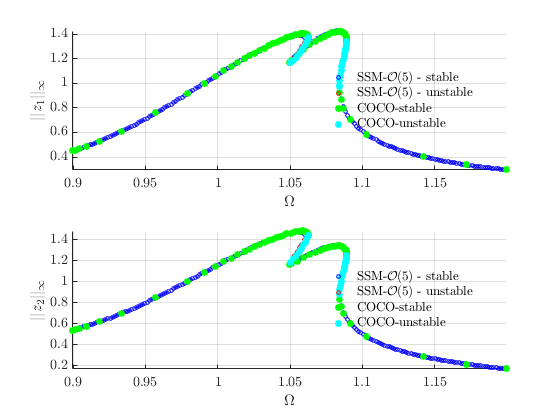


 The first 4 eigenvalues are given as 
  -0.0100 + 0.9999i
  -0.0100 - 0.9999i
  -0.0100 + 1.7320i
  -0.0100 - 1.7320i



sigma_out = 1
sigma_in = 1


parSubRange =     0.9000    1.1999


*****************************************
Calculating FRC using SSM with master subspace: [1  2]
sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.90E-03 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 9.23E-03 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.14E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.41E-02 MB
gamma = 
  -0.0150 + 0.0749i
  -0.0008 - 0.0081i



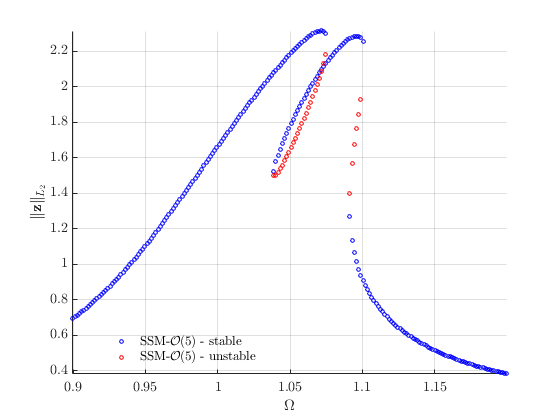

Total time spent on FRC computation upto O(5) = 00:00:55



 Run='FRC1': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.34e-01  1.23e+01    0.0    0.0    0.0
   1   1  3.66e-01  2.80e+00  1.48e-01  1.19e+01    0.0    0.0    0.0
   2   1  5.29e-01  1.83e+00  6.99e-02  1.15e+01    0.0    0.1    0.0
   3   1  1.00e+00  8.89e-01  2.81e-04  1.12e+01    0.0    0.1    0.0
   4   1  1.00e+00  1.28e-02  9.21e-08  1.12e+01    0.0    0.1    0.0
   5   1  1.00e+00  5.28e-06  1.60e-14  1.12e+01    0.0    0.1    0.0
   6   1  1.00e+00  9.95e-13  2.98e-15  1.12e+01    0.0    0.2    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1         amp2
    0  00:00:00   1.1152e+01      1  EP      8.9995e-01   6.9817e+00   1.0000e+00   4.7108e-01   5.5923e-01
    1  00:00:00   1.1041e+01      2  EP      8.9995e-01   6.9817e+00   1.0000e+00   4.7114e-01

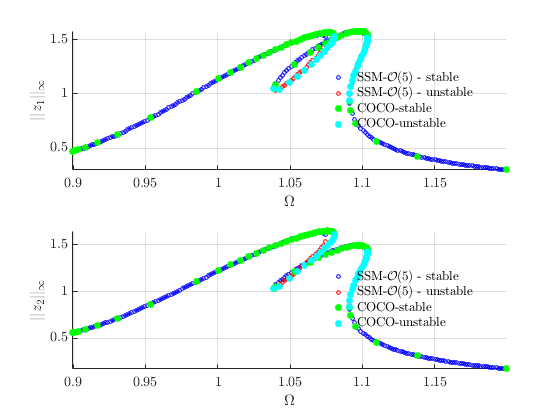


 The first 4 eigenvalues are given as 
  -0.0100 + 0.9999i
  -0.0100 - 0.9999i
  -0.0100 + 1.7320i
  -0.0100 - 1.7320i



sigma_out = 1
sigma_in = 1


parSubRange =     0.9000    1.1999


*****************************************
Calculating FRC using SSM with master subspace: [1  2]
sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.90E-03 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 9.23E-03 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.14E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.41E-02 MB
gamma = 
  -0.0150 + 0.0749i
  -0.0008 - 0.0081i



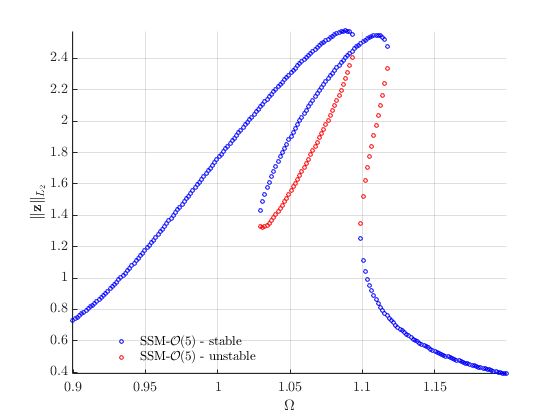

Total time spent on FRC computation upto O(5) = 00:00:48



 Run='FRC1': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.45e-01  1.26e+01    0.0    0.0    0.0
   1   1  3.66e-01  2.82e+00  1.55e-01  1.21e+01    0.0    0.0    0.0
   2   1  5.38e-01  1.83e+00  7.17e-02  1.18e+01    0.0    0.1    0.0
   3   1  1.00e+00  8.64e-01  2.65e-04  1.15e+01    0.0    0.1    0.0
   4   1  1.00e+00  1.24e-02  9.29e-08  1.15e+01    0.0    0.1    0.0
   5   1  1.00e+00  5.78e-06  2.00e-14  1.15e+01    0.0    0.1    0.0
   6   1  1.00e+00  1.32e-12  3.15e-15  1.15e+01    0.0    0.2    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1         amp2
    0  00:00:00   1.1523e+01      1  EP      8.9995e-01   6.9817e+00   1.0000e+00   4.9974e-01   5.8639e-01
    1  00:00:00   1.1400e+01      2  EP      8.9995e-01   6.9817e+00   1.0000e+00   4.9975e-01

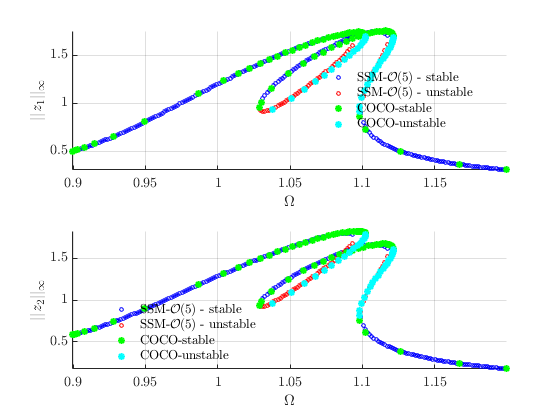

nCycles = 10;

coco = cocoWrapper(DS, nCycles, outdof);
set(coco,'initialGuess','forward')
set(coco.Options, 'NAdapt', 1);
set(coco.Options,'ItMX',10,'NTST', 30,'PtMX',200); %for convergence, smaller stepsize

figure(figFRC)
hold on;
startcoco = tic;
bds(ii).bd = coco.extract_FRC(OmegaRange);
timings(ii).cocoFRC = toc(startcoco);

ii = ii+1;
end

for i = 1:numel(timings)
    timings(i)
end

ans = struct with fields:
     FRCSSM: 78.6288
    cocoFRC: 44.4230


ans = struct with fields:
     FRCSSM: 72.5499
    cocoFRC: 33.7054


ans = struct with fields:
     FRCSSM: 56.5424
    cocoFRC: 37.4164


ans = struct with fields:
     FRCSSM: 49.0596
    cocoFRC: 34.5413


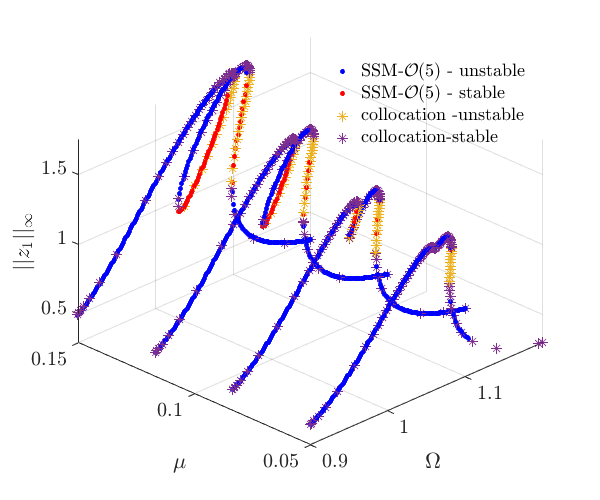


PaperFigureSweep(FRCs,bds,1,order,mus)